% Capacitance Calculator

% handling the geometry
a = 1e-2, b = 1e-2, d = 3e-3

a = 0.0100

b = 0.0100

d = 0.0030

nx = 50, ny = 50, eps = 1e-8

nx = 50

ny = 50

eps = 1.0000e-08

e0 = 8.85e-12

e0 = 8.8500e-12

N = nx*ny*2

N = 5000


% r matrix for patch locations storage
r = zeros(N, 3);

delx = a/nx;
dely = b/ny;
dels = delx*dely;

cnt = 0;

% looping to store the patch locations
for k = 1:2
    for i = 1:nx
        for j = 1:ny
            cnt = cnt + 1;

            r(cnt, 1) = delx*(i-1);
            r(cnt, 2) = dely*(j-1);
            r(cnt, 3) = d*(k-1);        
        end
    end
end

% handling the main solver
Z = zeros(N, N);

for i = 1:N
    for j = 1:N
        Rmn = norm(r(i, :) - r(j, :));
        
        % two far patches
        if Rmn >= (delx - eps)
            Z(i, j) = 1 / ( 4*pi*e0*Rmn );

        % two close patches
        elseif Rmn < (delx - eps) && Rmn > eps
            Z(i, j) = (1/(2*e0*dels))*(-d + sqrt( (dels/pi) + d^2 ));

        % self patches
        else
            Z(i, j) = 1 / ( 2*e0*sqrt(pi*dels) );    
        end
    end
end

% post processing
% Problem 2

V0 = 2

V0 = 2

V = zeros(N, 1);
V(1:N/2, :) = ones(N/2, 1)*(V0/2);
V((N/2+1):N, :) = ones(N/2, 1)*(-V0/2);

Q = inv(Z)*V

Q = 	1.0e+-14 *

    0.2282
    0.1506
    0.1368
    0.1289
    0.1240
    0.1208
    0.1184
    0.1166
    0.1153
    0.1142


Qtotal = sum(Q(1:N/2));
C = Qtotal/V0

C = 5.2436e-13

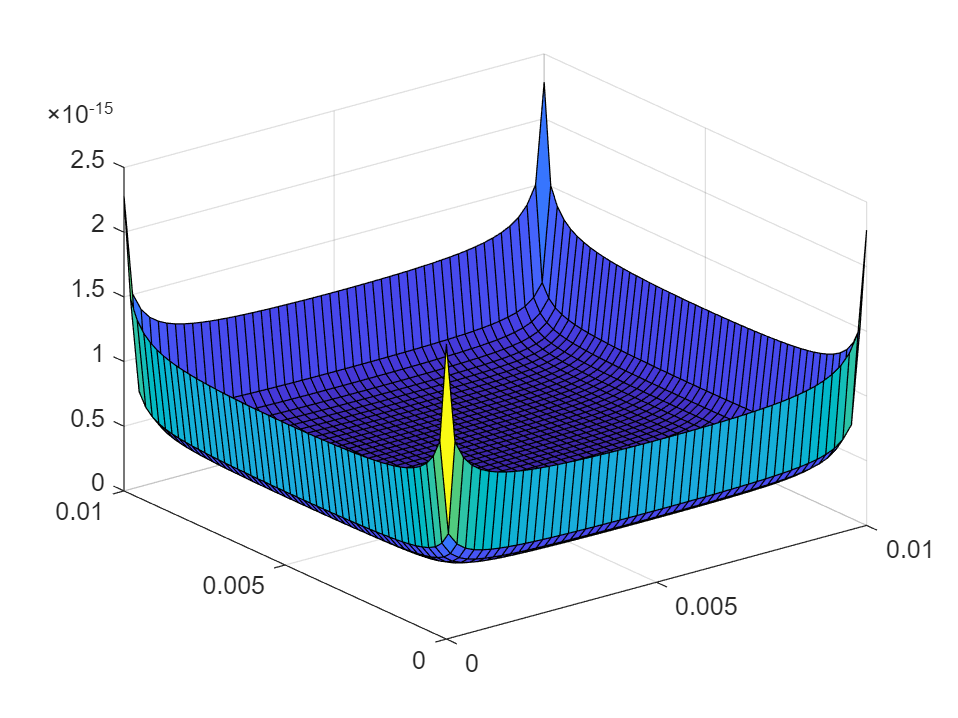

% Problem 3
Qtop = Q(1:N/2, 1);
Qdis = reshape(Qtop, ny, nx);

x_tick = linspace(0, a, nx);
y_tick = linspace(0, b, ny);
[X, Y] = meshgrid(x_tick, y_tick);

surf(X, Y, Qdis)

% Problem 4
dmin = 1e-4

dmin = 1.0000e-04

dmax = 4e-2

dmax = 0.0400


d_list = linspace(dmin, dmax, 77)

d_list =     0.0001    0.0006    0.0011    0.0017    0.0022    0.0027    0.0032    0.0038    0.0043    0.0048    0.0053    0.0059    0.0064    0.0069    0.0075    0.0080    0.0085    0.0090    0.0095    0.0101    0.0106    0.0111    0.0116    0.0122    0.0127    0.0132    0.0137    0.0143    0.0148    0.0153    0.0158    0.0164    0.0169    0.0174    0.0180    0.0185    0.0190    0.0195    0.0200    0.0206    0.0211    0.0216    0.0221    0.0227    0.0232    0.0237    0.0242    0.0248    0.0253    0.0258


C_cal = [];

for i = 1:length(d_list)
    d = d_list(i);

    r = get_loc(N, nx, ny, delx, dely, d);
    Z = get_Z(N, r, delx, eps, e0, dels, d);

    Q = inv(Z)*V;
    Qtotal = sum(Q(1:N/2));
    C = Qtotal/V0;

    C_cal = [C_cal C];
end

C_theo = (e0*a*b)./d_list

C_theo = 	1.0e+-11 *

    0.8850    0.1416    0.0770    0.0528    0.0402    0.0325    0.0272    0.0234    0.0206    0.0183    0.0165    0.0151    0.0138    0.0128    0.0119    0.0111    0.0104    0.0098    0.0093    0.0088    0.0083    0.0080    0.0076    0.0073    0.0070    0.0067    0.0064    0.0062    0.0060    0.0058    0.0056    0.0054    0.0052    0.0051    0.0049    0.0048    0.0047    0.0045    0.0044    0.0043    0.0042    0.0041    0.0040    0.0039    0.0038    0.0037    0.0036    0.0036    0.0035    0.0034


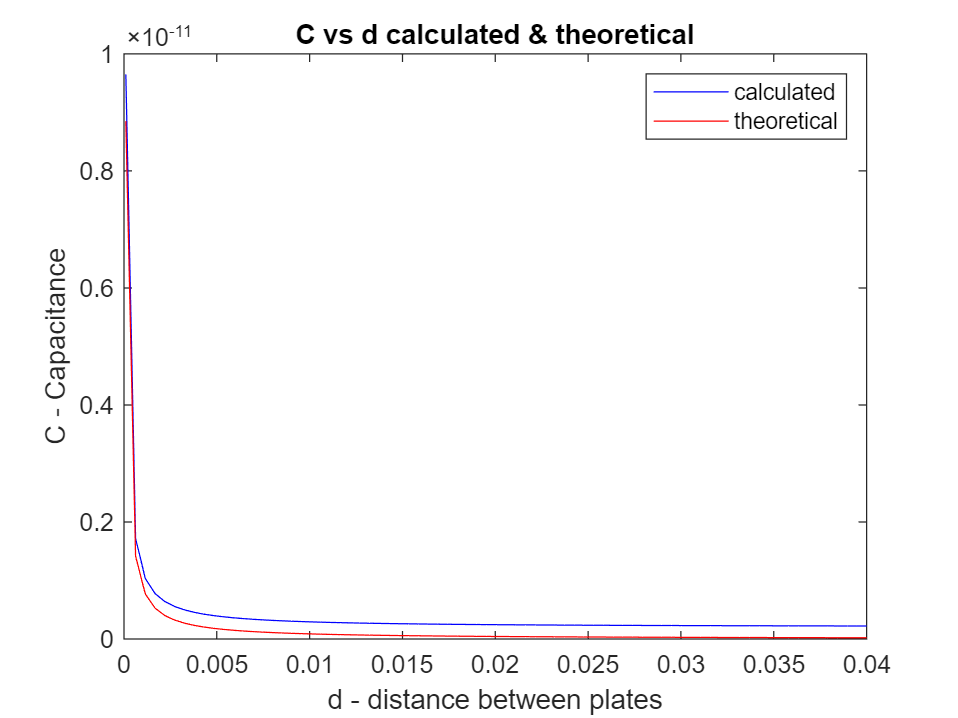


figure
plot(d_list, C_cal, 'blue')

hold on
plot(d_list, C_theo, 'red')
title('C vs d calculated & theoretical')
xlabel('d - distance between plates')
ylabel('C - Capacitance')
legend('calculated', 'theoretical')
hold off

Comment on when this formula is closer to the results obtained via the numerical solution:

The formula $C = \epsilon_0 w^2/d$ is closer to the results obtained via the numerical solution when the distance d between the two plates of the capacitor are smaller than 1mm.

function r = get_loc(N, nx, ny, delx, dely, d)
    r = zeros(N, 3);
    cnt = 0;

    % looping to store the patch locations
    for k = 1:2
        for i = 1:nx
            for j = 1:ny
                cnt = cnt + 1;

                r(cnt, 1) = delx*(i-1);
                r(cnt, 2) = dely*(j-1);
                r(cnt, 3) = d*(k-1);
            end
        end
    end

end


% handling the main solver
function Z = get_Z(N, r, delx, eps, e0, dels, d)
    Z = zeros(N, N);

    for i = 1:N
        for j = 1:N
            Rmn = norm(r(i, :) - r(j, :));
            
            % two far patches
            if Rmn >= (delx - eps)
                Z(i, j) = 1 / ( 4*pi*e0*Rmn );
    
            % two close patches
            elseif Rmn < (delx - eps) && Rmn > eps
                Z(i, j) = (1/(2*e0*dels))*(-d + sqrt( (dels/pi) + d^2 ));
    
            % self patches
            else
                Z(i, j) = 1 / ( 2*e0*sqrt(pi*dels) );    
            end
        end
    end

end